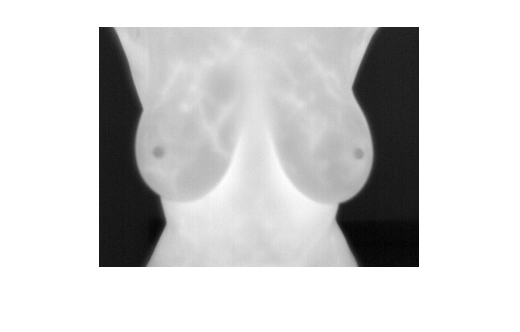

body = imread("IR_0100.png");
body = body(:,:, 1);
%body = imread('cameraman.tif');
imshow(body)

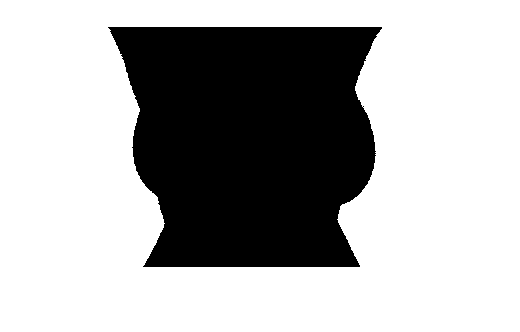


mask = body < 50;
imshow(mask)

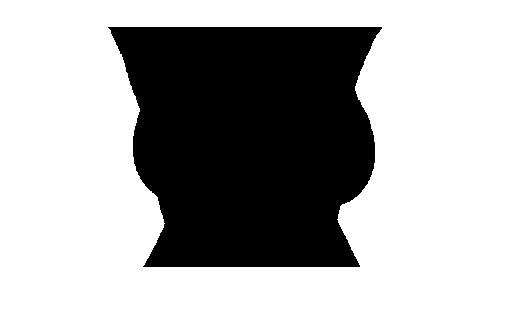



% structuring element
se_close = strel('disk',3);
closed_mask = imclose(mask, se_close);
imshow(closed_mask)

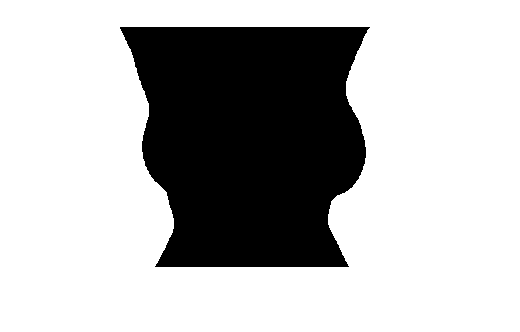


se_dilate = strel('disk',10);
dilated_mask = imdilate(closed_mask, se_dilate);
imshow(dilated_mask)

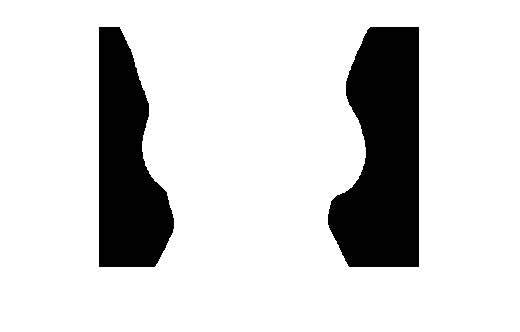


mask = imcomplement(dilated_mask);
imshow(mask)

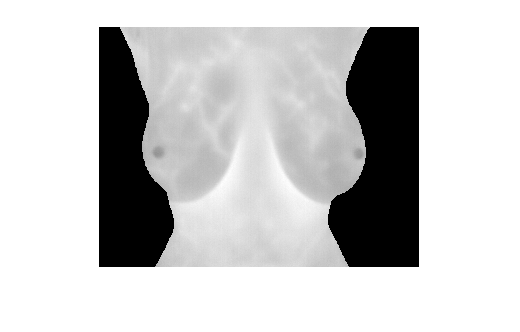



masked_body = bsxfun(@times, body, cast(mask,class(body)));
imshow(masked_body)


imwrite(masked_body, 'masked.png');
